 
clear
timerOverall = tic;
fprintf(['Beginning Script...' newline]);

Beginning Script...


[scenario, testName] = kidneyBeanTest;
video1 = true;
video2 = true;
video3 = true;
formationGIF = true;

bounds = roadBoundaries(scenario);

outerBounds = flip(bounds{1}(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));

centersDiff = [0; sqrt(sum((centers(2:end,:)-centers(1:end-1,:)).^2,2))];
sVals = cumsum(centersDiff);

normFactor = floor(sVals(end))/sVals(end);

innerBoundsNormalized = innerBounds.*normFactor;
centersNormalized = centers.*normFactor;
outerBoundsNormalized = outerBounds.*normFactor;
sValsNormalized = sVals.*normFactor;

waypoints = [spline(sValsNormalized, centersNormalized(:,1),0:sValsNormalized(end))',...
             spline(sValsNormalized, centersNormalized(:,2),0:sValsNormalized(end))'];

boundaryPointsNormalized = [spline(sValsNormalized, innerBoundsNormalized(:,1), 0:sValsNormalized(end))',...
                            spline(sValsNormalized, innerBoundsNormalized(:,2), 0:sValsNormalized(end))',...
                            spline(sValsNormalized, outerBoundsNormalized(:,1), 0:sValsNormalized(end))',...
                            spline(sValsNormalized, outerBoundsNormalized(:,2), 0:sValsNormalized(end))'];

fprintf(['Beginning Optimization' newline])

Beginning Optimization


timeOptimization = tic;
[waypointsFit, videoSet, videoSetPt, sFit] = discreteWaypointOptimizer(waypoints, normFactor*3, 50, 0.005, 0.2, 0.2, testName);

Iteration: 1.000000 | k: 13.901925
Iteration: 2.000000 | k: 13.832081
Iteration: 3.000000 | k: 13.787306
Iteration: 4.000000 | k: 13.741383
Iteration: 5.000000 | k: 13.695537
Iteration: 6.000000 | k: 13.649609
Iteration: 7.000000 | k: 13.603729
Iteration: 8.000000 | k: 13.557795
Iteration: 9.000000 | k: 13.511999
Iteration: 10.000000 | k: 13.413396
Iteration: 11.000000 | k: 13.541277
Iteration: 12.000000 | k: 13.525484
Iteration: 13.000000 | k: 13.449423
Iteration: 14.000000 | k: 13.459693
Iteration: 15.000000 | k: 13.366215
Iteration: 16.000000 | k: 13.355939
Iteration: 17.000000 | k: 13.338137
Iteration: 18.000000 | k: 13.250292
Iteration: 19.000000 | k: 13.231861
Iteration: 20.000000 | k: 13.219364
Iteration: 21.000000 | k: 13.216819


timeOptimizationOut = toc(timeOptimization);
fprintf(['Optimization Complete: %f sec' newline],timeOptimizationOut);

Optimization Complete: 63.776618 sec


Beginning Video Output By Iteration...


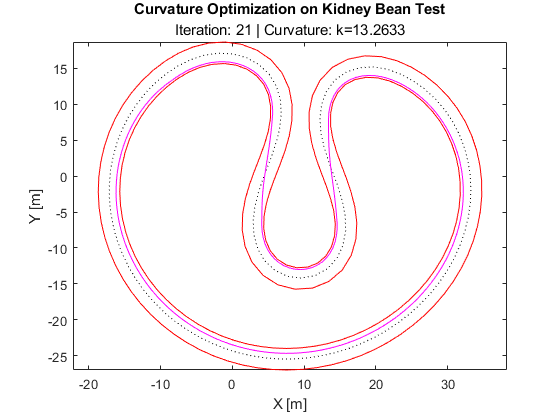

Video 1 Complete: 4.270638 sec



videoSet(:,1) = cellfun(@(x) x/normFactor, videoSet(:,1), 'un',0);
videoSetPt(:,1) = cellfun(@(x) x/normFactor, videoSetPt(:,1), 'un',0);

videoSet(:,3) = cellfun(@(x) x/normFactor, videoSet(:,3), 'un',0);
videoSetPt(:,3) = cellfun(@(x) x/normFactor, videoSetPt(:,3), 'un',0);

waypointsFit = waypointsFit./normFactor;

[velocityProfile, minTLap] = velocityProfiler(0.001, [waypointsFit(1:end-1,:); waypointsFit(1:end-1,:); waypointsFit(:,:)], sFit, 4*300, 0.5*300, 300);
iterationEnd = videoSet{end,2};
curvatureEnd = videoSet{end,3};



if video1
    fprintf(['Beginning Video Output By Iteration...' newline]);
    timeVideo1 = tic;
    writer1(videoSet, testName, centers, innerBounds, outerBounds);
    timeVideo1Out = toc(timeVideo1);
    fprintf(['Video 1 Complete: %f sec' newline],timeVideo1Out);
end

Beginning Video Output By Point...


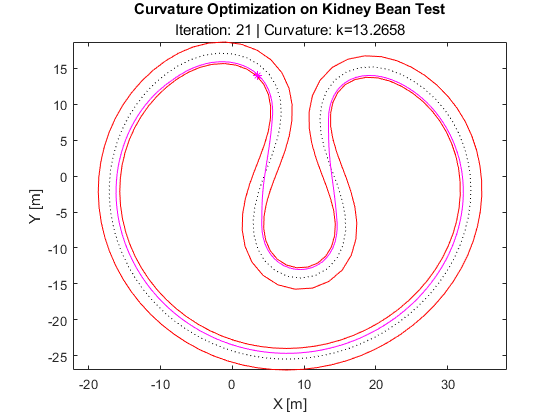

Video 2 Complete: 855.589142 sec



if video2
    fprintf(['Beginning Video Output By Point...' newline]);
    timeVideo2 = tic;
    writer2(videoSetPt, testName, centers, innerBounds, outerBounds);
    timeVideo2Out = toc(timeVideo2);
    fprintf(['Video 2 Complete: %f sec' newline],timeVideo2Out);
end

Beginning Video Output By Velocity...


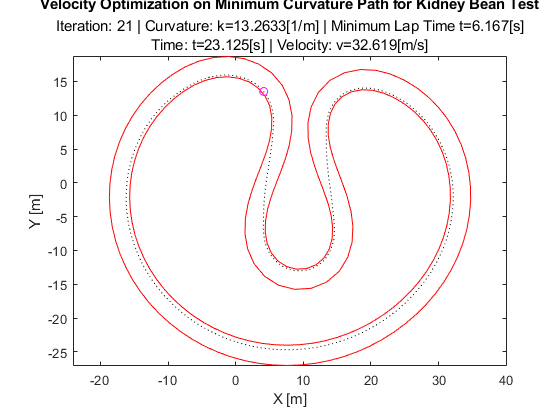

Velocity Video Complete: 182.455262 sec



if video3
    fprintf(['Beginning Video Output By Velocity...' newline]);
    timeVideo3 = tic;
    writer3(velocityProfile, 40, testName, waypointsFit, innerBounds, outerBounds, minTLap, iterationEnd, curvatureEnd);
    timeVideo3Out = toc(timeVideo3);
    fprintf(['Velocity Video Complete: %f sec' newline],timeVideo3Out);
end

Beginning GIF Output...


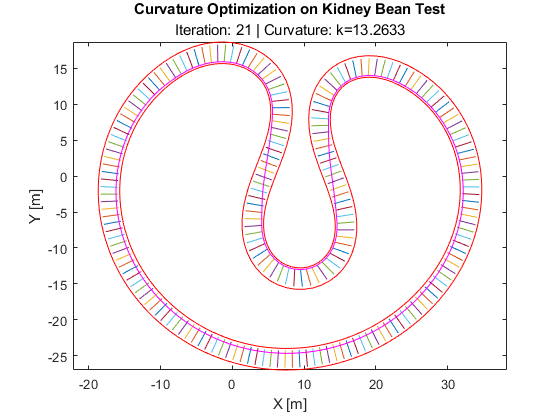

GIF Complete: 16.928290 sec



if formationGIF
    fprintf(['Beginning GIF Output...' newline]);
    timeGIF = tic;
    gifWriter(videoSet, testName, boundaryPointsNormalized/normFactor, normFactor)
    timeGIFOut = toc(timeGIF);
    fprintf(['GIF Complete: %f sec' newline],timeGIFOut);
end



if ~video1 && ~video2 && ~video3 && ~formationGIF
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        waypointsFit(:,1), waypointsFit(:,2), 'm',...
        'Visible',"on");
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{end,2}),' | Curvature: k=',num2str(videoSet{end,3})]);
end

fprintf(['Script Complete: %f sec' newline], toc(timerOverall))

Script Complete: 1124.399029 sec


function writer1(videoSet, testName, centers, innerBounds, outerBounds)
clf;
writer = VideoWriter(testName(testName ~= ' '));
writer.FrameRate = 1;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer2(videoSet, testName, centers, innerBounds, outerBounds)
clf;
writer = VideoWriter([testName(testName ~= ' '),'ByPt']);
writer.FrameRate = 60;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    plot(videoSet{idxVidSet,4}(1), videoSet{idxVidSet,4}(2),'*m');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer3(videoSet, fps, testName, minCurPath, innerBounds, outerBounds, minTLap, itEnd, kEnd)
clf;
writer = VideoWriter([testName(testName ~= ' '),'ByVel']);
writer.FrameRate = fps;
skipFactor = (1/fps)*(1/(videoSet(2,2)-videoSet(1,2)));
open(writer);
for idxVidSet = 1:skipFactor:size(videoSet,1)
    plot(minCurPath(:,1), minCurPath(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet(idxVidSet,4), videoSet(idxVidSet,5), 'mo',...
        'Visible',"on");
    hold on
    title(['Velocity Optimization on Minimum Curvature Path for ',testName],['Iteration: ',num2str(itEnd,'%.0f'),' | Curvature: k=',num2str(kEnd),'[1/m] | Minimum Lap Time t=',num2str(minTLap,'%.3f'),'[s]', newline,'Time: t=',num2str(videoSet(idxVidSet,2),'%.3f'),'[s] | Velocity: v=',num2str(videoSet(idxVidSet,1),'%.3f'), '[m/s]']);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function gifWriter(videoSet, testName, inOutBounds, normFactor)
clf;
fileName = [testName(testName ~= ' '), '.gif'];
plot(inOutBounds(:,1), inOutBounds(:,2), 'r',...
     inOutBounds(:,3), inOutBounds(:,4), 'r');
title(['Curvature Optimization on ',testName],['Iteration: 0 | Curvature: k=0.000']);
axis equal;
xlabel('X [m]');
ylabel('Y [m]');
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','LoopCount',Inf,'DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['emptyTrack', testName(testName ~= ' '), '.png']);
hold on
plot(videoSet{1,1}(:,1), videoSet{1,1}(:,2), ' *m', 'MarkerSize', 1);
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['trackWaypoints', testName(testName ~= ' '), '.png']);
for idxWP = 1:length(videoSet{1,1})-1
    angTemp = atan2(videoSet{1,1}(idxWP+1,2)-videoSet{1,1}(idxWP,2), videoSet{1,1}(idxWP+1,1)-videoSet{1,1}(idxWP,1));   
    rotLinePoints = [0, (-normFactor*3/2)*(1-0.2); 0, (normFactor*3/2)*(1-0.2)]*[cos(-angTemp) -sin(-angTemp); sin(-angTemp) cos(-angTemp)]+[videoSet{1,1}(idxWP,1), videoSet{1,1}(idxWP,2)];
    plot([rotLinePoints(2,1), rotLinePoints(1,1)], [rotLinePoints(2,2), rotLinePoints(1,2)],"LineWidth",0.3,'Marker','none');
end
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['waypointChords', testName(testName ~= ' '), '.png']);
hold off

for idxVidSet = 1:size(videoSet,1)
    plot(inOutBounds(:,1), inOutBounds(:,2), 'r',...
        inOutBounds(:,3), inOutBounds(:,4), 'r');
    hold on
    for idxWP = 1:length(videoSet{1,1})-1
        angTemp = atan2(videoSet{1,1}(idxWP+1,2)-videoSet{1,1}(idxWP,2), videoSet{1,1}(idxWP+1,1)-videoSet{1,1}(idxWP,1));
        rotLinePoints = [0, (-normFactor*3/2)*(1-0.2); 0, (normFactor*3/2)*(1-0.2)]*[cos(-angTemp) -sin(-angTemp); sin(-angTemp) cos(-angTemp)]+[videoSet{1,1}(idxWP,1), videoSet{1,1}(idxWP,2)];
        plot([rotLinePoints(2,1), rotLinePoints(1,1)], [rotLinePoints(2,2), rotLinePoints(1,2)],"LineWidth",0.3,'Marker','none');
    end
    plot(videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    [gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
    imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',0.25);
end
imwrite(frame2im(getframe(gcf)), ['waypointFinal', testName(testName ~= ' '), '.png']);
end
% [ai] a(v=0) = 0
% [av] a(v=20) = 3
% [am] a(v=40) = 6
% da/dv = ra((am-a)/am)
% da/dt max = 2
% dv/dt max = 5
% dp/dt max = 40
% a = am/(1+be^(-kv))
% 